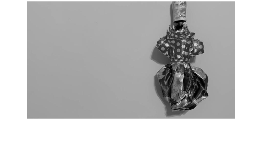

% CV Homework-3 Question 6

img = imread('Image295.jpg');
boxImg = rgb2gray(img);
figure;
imshow(boxImg);
title('Image of a Box');

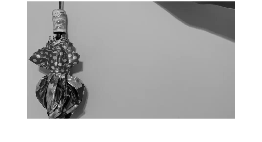

img2 = imread('Image1.jpg');
sceneImg = rgb2gray(img2);
figure;
imshow(sceneImg);
title('Image of a scene');

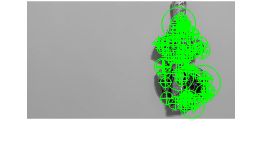

boxImgPoints = detectSURFFeatures(boxImg);

sceneImgPoints = detectSURFFeatures(sceneImg);
figure;
imshow(boxImg);
title('Top Strongest Feature Points from Box Image');
hold on;
plot(selectStrongest(boxImgPoints, 100));

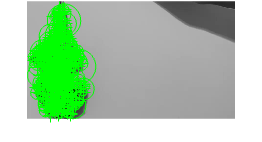

figure;
imshow(sceneImg);
title('Top Strongest Feature Points from Scene Image');
hold on;

plot(selectStrongest(sceneImgPoints, 300));

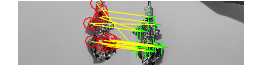


[boxImgFeatures, boxImgPoints] = extractFeatures(boxImg, boxImgPoints);
[sceneImgFeatures, sceneImgPoints] = extractFeatures(sceneImg, sceneImgPoints);


boxImgPairs = matchFeatures(boxImgFeatures, sceneImgFeatures);
matchedBoxImgPoints = boxImgPoints(boxImgPairs(:, 1), :);
matchedSceneImgPoints = sceneImgPoints(boxImgPairs(:, 2), :);
figure;
showMatchedFeatures(boxImg, sceneImg, matchedBoxImgPoints, ...
    matchedSceneImgPoints, 'montage');


title('Matched Points (Including Outliers)');

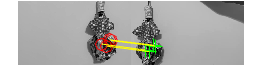

[tform, inlierIdx] = ...
    estimateGeometricTransform2D(matchedBoxImgPoints, matchedSceneImgPoints, 'affine');
inlierBoxImgPoints   = matchedBoxImgPoints(inlierIdx, :);
inlierSceneImgPoints = matchedSceneImgPoints(inlierIdx, :);
figure;
showMatchedFeatures(boxImg, sceneImg, inlierBoxImgPoints, ...
    inlierSceneImgPoints, 'montage');


title('Matched Points (Inliers Only)');

boxImgPolygon = [1, 1;...                           
        size(boxImg, 2), 1;...                 
        size(boxImg, 2), size(boxImg, 1);... 
        1, size(boxImg, 1);...                 
        1, 1];                  
newBoxImgPolygon = transformPointsForward(tform, boxImgPolygon)

newBoxImgPolygon = 5×2 single matrix
 -413.6726   99.4868
  410.2714   38.1613
  276.7426  504.7996
 -547.2014  566.1250
 -413.6726   99.4868


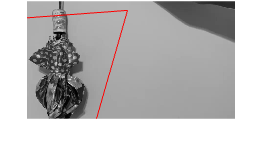

figure;
imshow(sceneImg);
hold on;
line(newBoxImgPolygon(:, 1), newBoxImgPolygon(:, 2), 'Color', 'r');
title('Detected Box');